# MAT 275 - LAB 4                                                     Bo-Chang Lin       

# Exercise 1

### **Part (a)**

**Solve the IVP**

$\frac{d^2 y}{{\mathrm{dt}}^2 }+5\frac{\mathrm{dy}}{\mathrm{dt}}+4y=5\sin \left(t\right),y\left(0\right)=-1,v\left(0\right)=0$  **Eqn. (4)**

type 'LAB04ex1.m'

t0 = 0; tf = 60; 
Y0 = [-1;0]; % [y(0); v(0)]

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2);    % Y in output has 2 columns corresponding to y and v

figure(1)
plot(t,y,'b',t,v,'r',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('$t$',"Interpreter","latex","FontSize",14); 
ylabel("$y,v=y'$","Interpreter","latex","FontSize",14)
legend('y(t)','v(t)',"Interpreter","latex")
title("$d^2y/dt^2+5dy/dt+4y=5sin(t), y(0)=-1, v(0)=0$","Interpreter","latex","FontSize",14)

figure(2)
plot(y,v,LineWidth=1);   % plot the phase plot
axis square 
ylim([-3.1,3.1])
xlim([-2.6,2.6])
grid on 

xlabel('$y$',"Interpreter","latex","FontSize",14); 
ylabel("$v=y'$","Interpreter","latex","FontSize",14)
title("Phase Plot","Interpreter","latex","FontSize",14)

%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; 5*sin(t)-5*v-4*y];
end


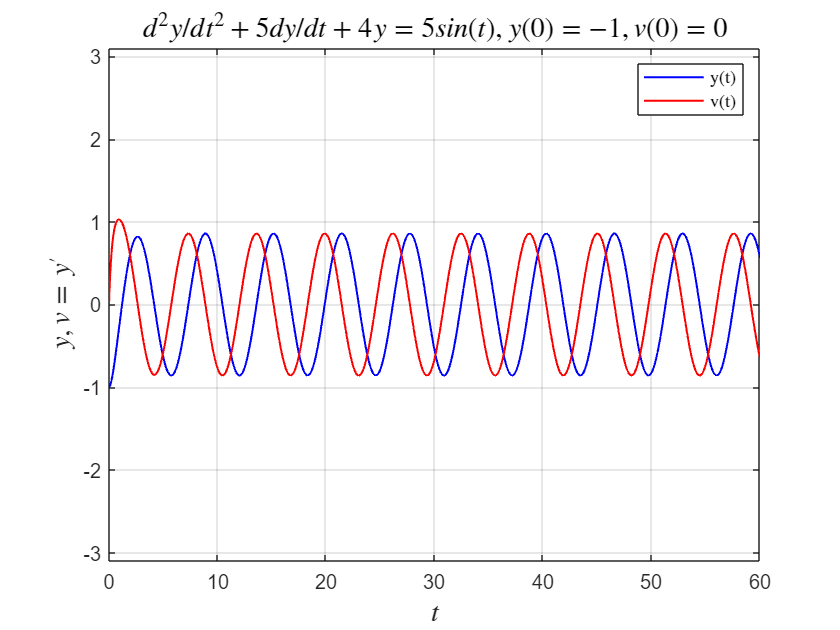

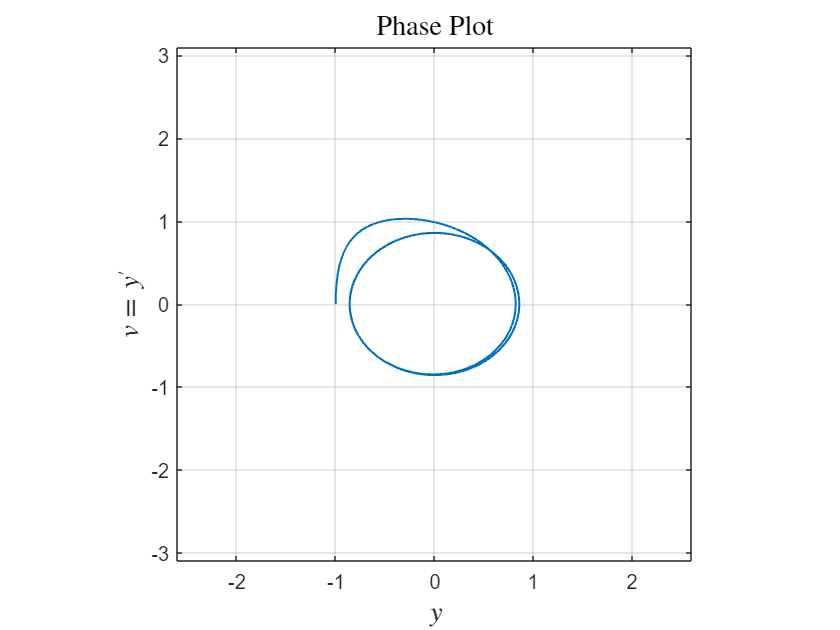

LAB04ex1                        % Fig. (7)

### **Part (b)**

Find (approximately) the last three values of **t** in the interval **[0,60]** at which **y** reaches a **local maximum**.

% Method 1 (local max only)
format short
[pks,locs] = findpeaks(y);
Data = [t(locs(end-2:end)),pks(end-2:end)];
T1 = array2table(Data);
T1.Properties.VariableNames(1:2) = {'t','y(t)'}

T1 = 3×2 table
      t        y(t)  
    ______    _______
    46.556    0.85719
    52.895    0.85717
     59.12    0.85713

% Method 2 (local max & min)
DATA1 = [t, Y(:,1), Y(:,2)];  
DATA2 = zeros(length(pks)*2,3);
j = 1;
for i = 1:length(Y)-1
    if Y(i,2)*Y(i+1,2) < 0
        DATA2(j,:)=DATA1(i,:);
        j=j+1;
        DATA2(j,:)=DATA1(i,:);      
    end
end
DATA2 = DATA2(end-6:end-1,:);
T2 = array2table(DATA2);
T2.Properties.VariableNames(1:3) = {'t','y(t)','v(t)'}

T2 = 6×3 table
      t         y(t)         v(t)   
    ______    ________    __________
    43.433    -0.85747    -0.0072995
    46.556     0.85719      0.023302
    49.705    -0.85732       -0.0173
    52.834     0.85707       0.02757
    55.998    -0.85745    -0.0091579
     59.12     0.85713      0.025378

% Method 2 modified (local max only)
data1 = [t, Y(:,1), Y(:,2)];  
data2 = zeros(length(pks),3);
j = 1;
for i = 1:length(Y)-1
    if (Y(i,2)*Y(i+1,2) < 0) && (Y(i,2) > Y(i+1,2))
        data2(j,:)=DATA1(i,:);
        j=j+1;
        data2(j,:)=DATA1(i,:);      
    end
end
data2 = data2(end-3:end-1,:);
T3 = array2table(data2);
T3.Properties.VariableNames(1:3) = {'t','y(t)','v(t)'}

T3 = 3×3 table
      t        y(t)        v(t)  
    ______    _______    ________
    46.556    0.85719    0.023302
    52.834    0.85707     0.02757
     59.12    0.85713    0.025378

### Part (c)

**What seems to be the long term behavior of y?**

The long term behavior of y values seems to be in the range of -0.857 to 0.857 as the phase plot can tell, it turn out like a sort of circle with radius about 0.86

### **Part (d)**

Modify the initial conditions to **y(0) = -1:5, v(0) = 1:3**

type LAB04ex1d

t0 = 0; tf = 60; 
Y0 = [-1.5;1.3];

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2);    % Y in output has 2 columns corresponding to y and v

figure
plot(t,y,'b',t,v,'r',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('t',"Interpreter","latex"); ylabel("y,v=y'","Interpreter","latex")
legend('y(t)','v(t)',"Interpreter","latex")
title(strcat('y"',"+5y'+4y=5sin(t)",' ,y(0)=-1.5,v(0)=1.3'),"Interpreter","latex")

figure
plot(y,v,LineWidth=1);   % plot the phase plot
axis square 
ylim([-3.1,3.1])
xlim([-2.6,2.6])
grid on 

xlabel('y',"Interpreter","latex"); ylabel("v=y'","Interpreter","latex")
title("Phase Plot","Interpreter","latex")

%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; 5*sin(t)-5*v-4*y];
end


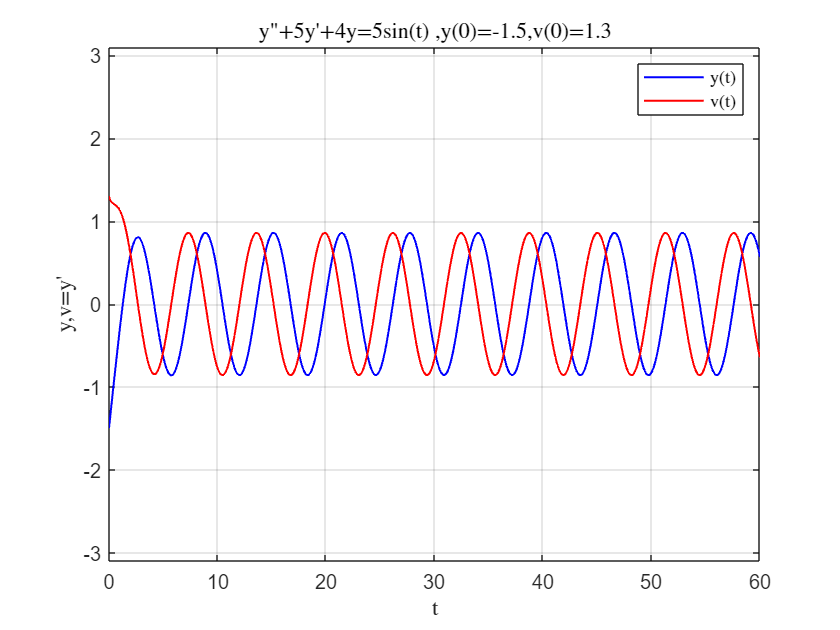

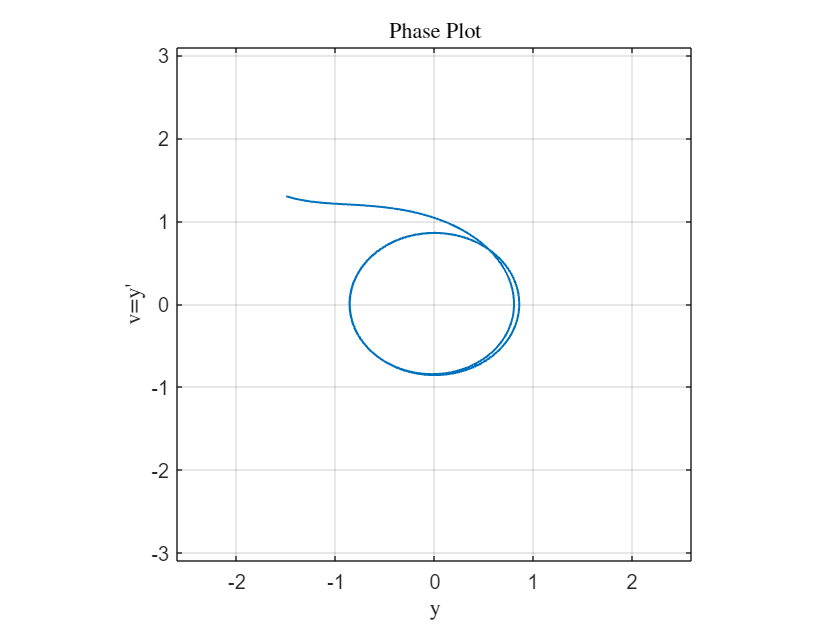

LAB04ex1d

**Based on the new graphs, determine whether the long term behavior of the solution changes.**

The long term behavior of y values will remain the same regardless of the change of initial conditions as the phase plot can tell, it turn out like a sort of circle with radius about 0.86

# Exercise 2

### Part (a)

**Modified IVP**

$\frac{d^2 y}{{\mathrm{dt}}^2 }+5y^2 \frac{\mathrm{dy}}{\mathrm{dt}}+4y=5\sin \left(t\right),y\left(0\right)=-1,v\left(0\right)=0$ **Eqn. (7)**

type  LAB04ex2

t0 = 0; tf = 60; 
Y0 = [-1;0];

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2);    % Y in output has 2 columns corresponding to y and v

figure
plot(t,y,'b',t,v,'r',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('t',"Interpreter","latex"); ylabel("y,v=y'","Interpreter","latex")
legend('y(t)','v(t)',"Interpreter","latex")
title(strcat('y"',"+(5y^2)y'+4y=5sin(t)",' ,y(0)=-1,v(0)=0'))

figure
plot(y,v,LineWidth=1);   % plot the phase plot
axis square 
ylim([-3.1,3.1])
xlim([-2.6,2.6])
grid on 

xlabel('y',"Interpreter","latex"); ylabel("v=y'","Interpreter","latex")
title("Phase Plot","Interpreter","latex")

%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; 5*sin(t)-5*y^2*v-4*y];
end


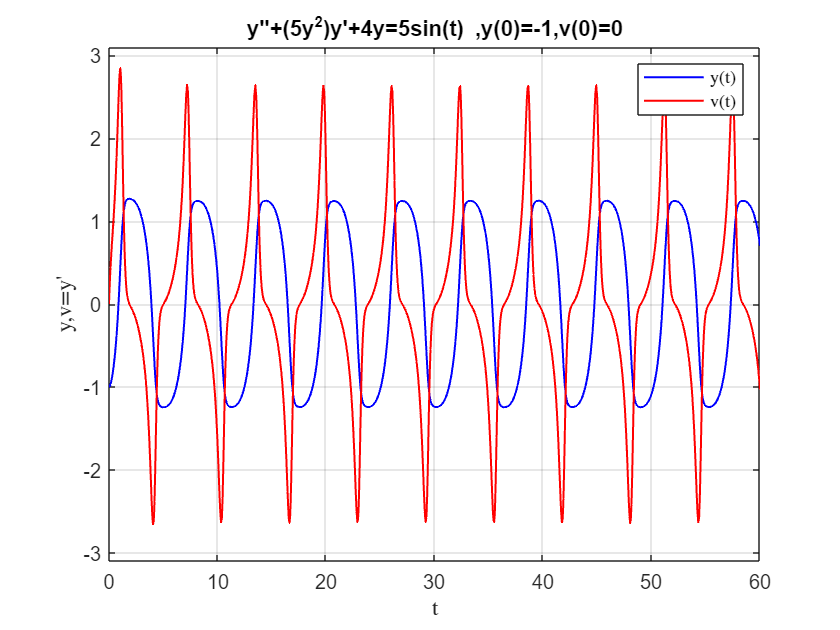

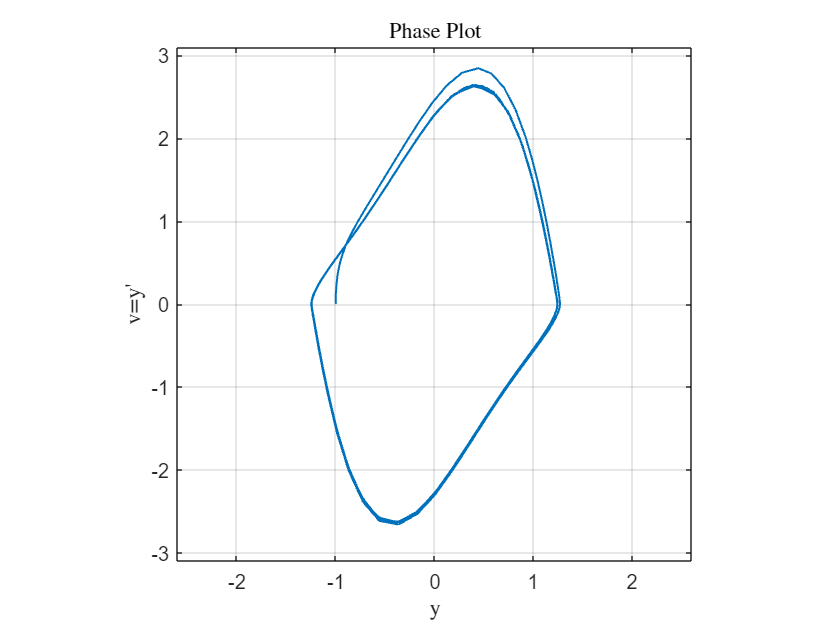

LAB04ex2                        % Fig. (8)

### Part (b)

**Compare the output of Figs. (7) and (8). Describe the changes in the behavior of the solution in**

**the short term.**

Comparing the two v(t), the later one has more drastically chage and the larger amplitude.

### Part (c)

**Compare the long term behavior of both problems Eqn. (4) and Eqn. (7), in particular the amplitude of**

**oscillations.**

For problem 7, it has the amplitude larger than 1 while for problem is about 0.86, on the other hand, the phase plot for p.7 is less symmetrical.

### Part (d)

Solves the ODE IVP using Euler's method with **N = 500**, and compare the result with **ode45**.

type LAB04ex2d

t0 = 0; tf = 60; 
Y0 = [-1;0];

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2);    % Y in output has 2 columns corresponding to y and v

[te,Ye] = euler(@f,[t0,tf],Y0,500);  % solve the ODE using Euler's 500 steps

figure
plot(t,y,'k',te,Ye(:,1),'r--',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('t',"Interpreter","latex"); ylabel("y,v=y'","Interpreter","latex")
legend('y(t)','Euler N = 500',"Interpreter","latex")
title(strcat('y"',"+(5y^2)y'+4y=5sin(t)",' ,y(0)=-1,v(0)=0'))



%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; 5*sin(t)-5*y^2*v-4*y];
end


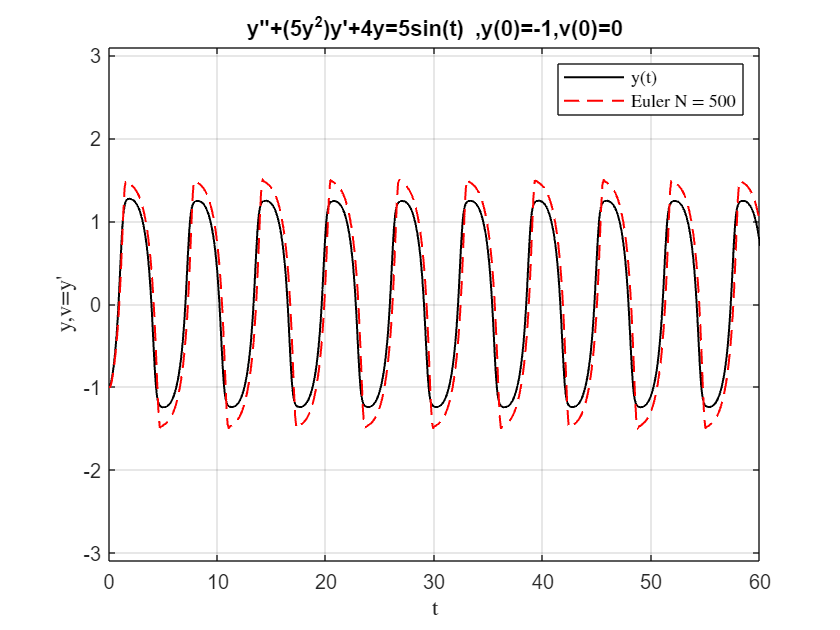

LAB04ex2d

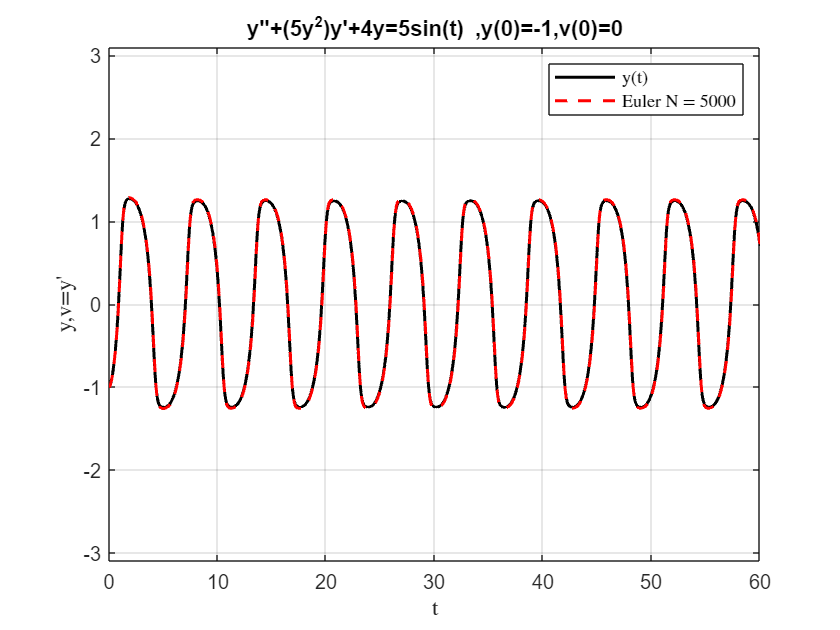

% Supplementary figure
LAB04ex2dnew

**Are the solutions identical? What happens if we increase the value of N?**

With Eular's N=500 approxmation, the solution is close but not quite identical in this case, but the accuracy will growth with the number of steps N increase.

# Exercise 3

**Another modified IVP **


$$\frac{d^2 y}{{\textrm{dt}}^2 }+5y\frac{\textrm{dy}}{\textrm{dt}}+4y=5\sin \left(t\right),y\left(0\right)=-1,v\left(0\right)=0$$


type LAB04ex3

t0 = 0; tf = 60; 
Y0 = [-1;0];

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2);    % Y in output has 2 columns corresponding to y and v

figure(1)
plot(t,y,'b',t,v,'r',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('t',"Interpreter","latex"); ylabel("y,v=y'","Interpreter","latex")
legend('y(t)','v(t)',"Interpreter","latex")
title(strcat('y"',"+(5y)y'+4y=5sin(t)",' ,y(0)=-1,v(0)=0'),"Interpreter","latex")

figure(2)
plot(y,v,LineWidth=1);   % plot the phase plot
axis square 
ylim([-3.1,3.1])
xlim([-2.6,2.6])
grid on 

xlabel('y',"Interpreter","latex"); ylabel("v=y'","Interpreter","latex")
title("Phase Plot","Interpreter","latex")

%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2);
dYdt = [v; 5*sin(t)-5*y*v-4*y];
end


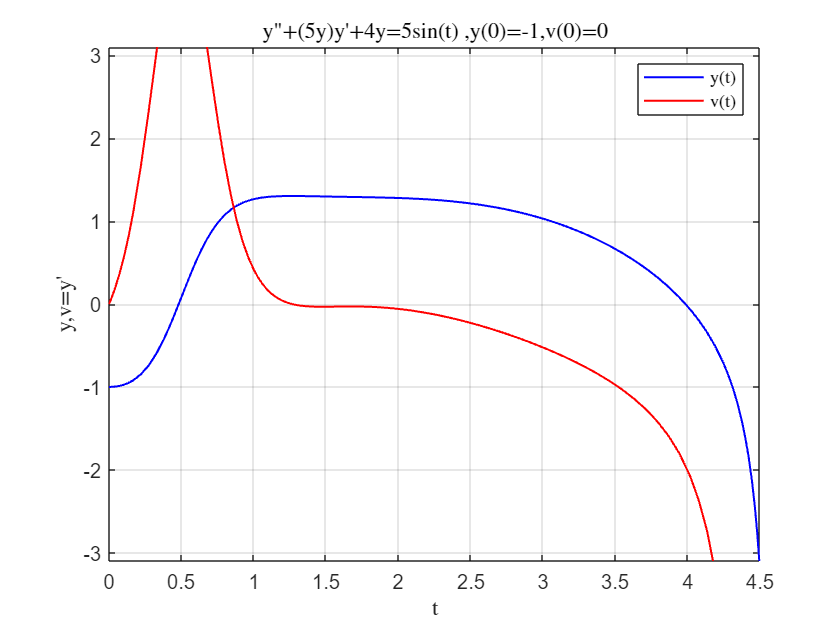

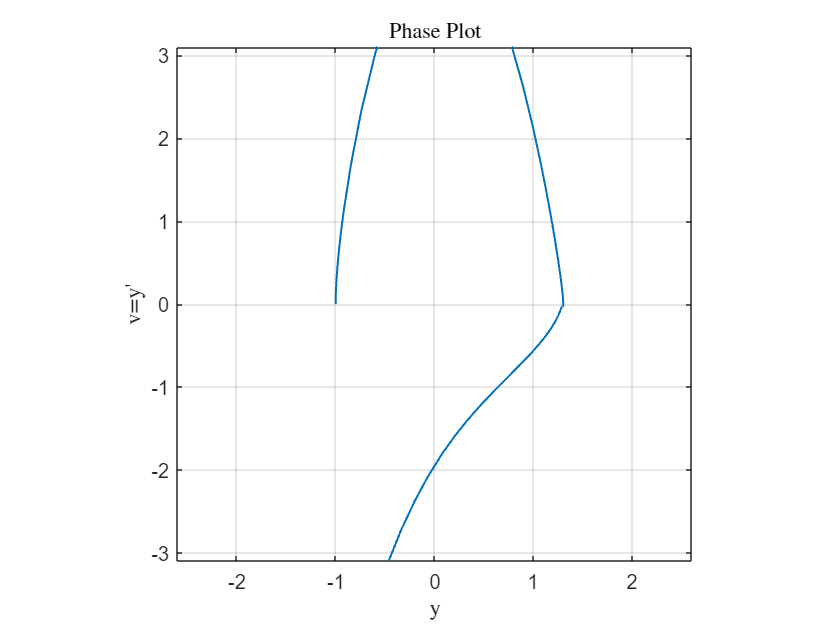

LAB04ex3

# Exercise 4

**A Third-Order Problem**

Consider the third-order IVP


$$\frac{d^3 y}{{\textrm{dt}}^3 }+5y^2 \frac{d^2 y}{{\textrm{dt}}^2 }+10{y\left(\frac{\textrm{dy}}{\textrm{dt}}\right)}^2 +4\frac{\textrm{dy}}{\textrm{dt}}=5\cos \left(t\right),y\left(0\right)=-1,v\left(0\right)=0,w\left(0\right)=-0\ldotp 5$$


type LAB04ex4

t0 = 0; tf = 60; 
Y0 = [-1;0;-0.5]; % [y(0); v(0); w(0)]

[t,Y] = ode45(@f,[t0,tf],Y0,[]);
y = Y(:,1); v = Y(:,2); w = Y(:,3);   % Y in output has 3 columns corresponding to y, v, and w

figure
plot(t,y,'b',t,v,'r',t,w,'k',LineWidth=1)
ylim([-3.1,3.1])
grid on

xlabel('t',"Interpreter","latex"); ylabel("y,v=y'","Interpreter","latex")
legend('y(t)','v(t)','w(t)',"Interpreter","latex")
title(strcat("y'''",'+5(y^2)y"',"+(10y)(y')^2+4y'=5sin(t)",' ,y(0)=-1,v(0)=0,w(0)=-0.5'))

figure
plot3(y,v,w,LineWidth=1);   % plot the phase plot
hold on;
view([-40, 60])  % Azimuth=-40 and Elevation=60 (Angle)
xlabel('y'); ylabel('v=y'''); zlabel('w=y''''');
grid on 

title("Phase Plot")

%----------------------------------------------------------------------
function dYdt = f(t,Y)
y=Y(1); v=Y(2); w=Y(3);
dYdt = [v; w; 5*cos(t)-5*y^2*w-10*y*v^2-4*v];
end


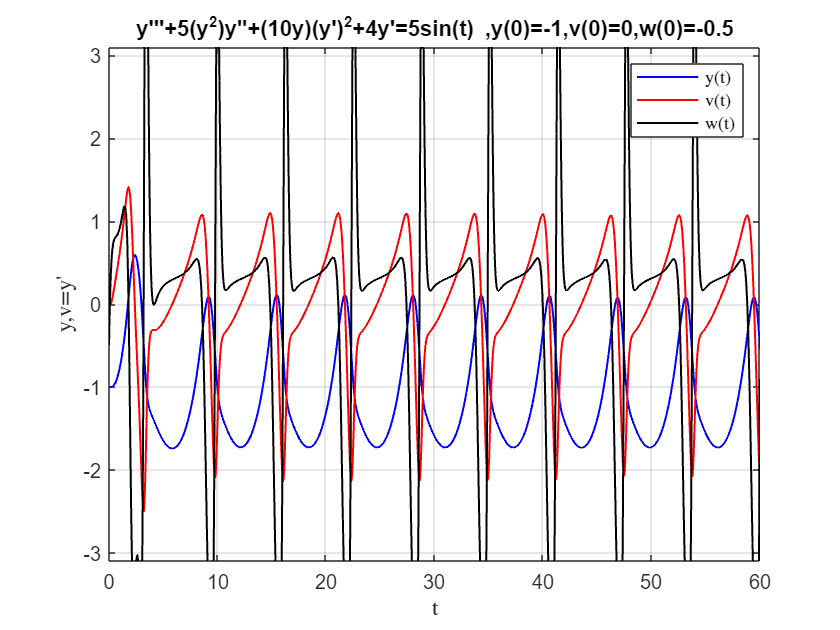

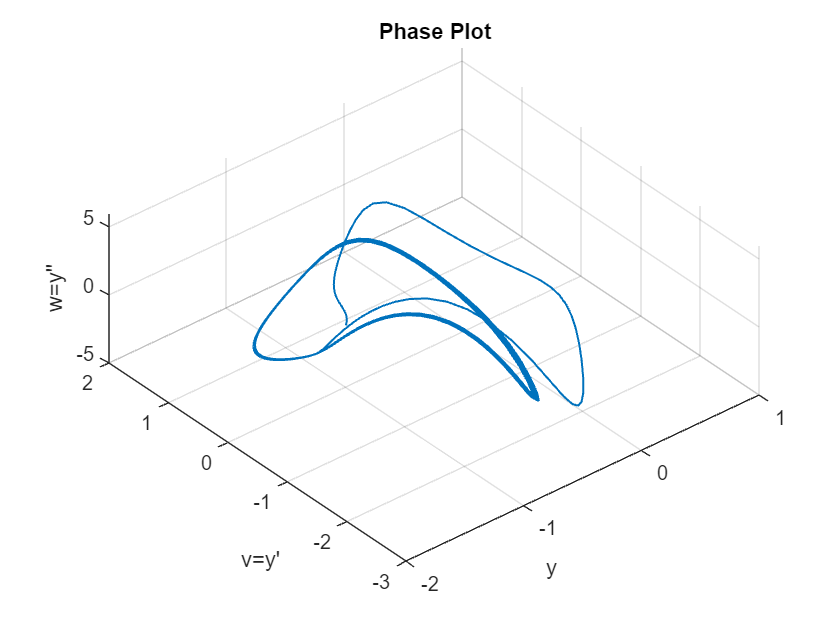

LAB04ex4